a = 1e-6;
N = 100; %discretize in real space
Nmode = 5;
nmode = 3;
kx_step = 0.025*4*pi/sqrt(3)/a; %discretize in reciprocal space
ky_step = 0.025*4*pi/sqrt(3)/a;
kx_start = -0.3*4*pi/sqrt(3)/a;
kx_end = 0.3*4*pi/sqrt(3)/a;
ky_start = -0.3*4*pi/sqrt(3)/a;
ky_end = 0.3*4*pi/sqrt(3)/a;
theta = 2*pi/3;

Nkx = round((kx_end-kx_start)/kx_step)+1;
Nky = round((ky_end-ky_start)/ky_step)+1;
delta_x = a/N;
delta_y = a/N*sqrt(3)/2;
delta_S = delta_x*delta_y;
xx = 0:delta_x:a;
yy = 0:delta_y:(a*sqrt(3)/2);
coord_mat = zeros(2,N*N);
for i = 1:N
    y_coord = yy(i)+0.5*delta_y;
    for j = 1:N
        x_coord = xx(j)+0.5*delta_x+yy(i)/sqrt(3)+delta_y/sqrt(3)/2;
        coord_mat(:,j+N*(i-1)) = [x_coord;y_coord];
    end
end
%Hx = mphinterp(model,'ewfd.Hx','coord',coord_mat);
%Hy = mphinterp(model,'ewfd.Hy','coord',coord_mat);
%Hz = mphinterp(model,'ewfd.Hz','coord',coord_mat);
%Ex = mphinterp(model,'ewfd.Ex','coord',coord_mat);
%Ey = mphinterp(model,'ewfd.Ey','coord',coord_mat);
Ez = mphinterp(model,'ewfd.Ez','coord',coord_mat);

eps = mphinterp(model,'ewfd.epsilonrxx','coord',coord_mat);


sum = 0;
berry = zeros(Nkx-1,Nky-1);
for i = 1:(Nkx-1)
    kx = kx_start + (i-1)*kx_step;
    for j = 1:(Nky-1)
        ky = ky_start + (j-1)*ky_step;
        %cur = berry_curvature(Hx,Hy,i,j,nmode,Nky,Nmode,delta_S);
        %cur = berry_curvature2(Hz,i,j,nmode,Nky,Nmode,delta_S,kx,ky,coord_mat);
        cur = berry_curvature3(Ez,eps,i,j,nmode,Nky,Nmode,delta_S,kx,ky,coord_mat);
        sum = sum + cur;
        cur = cur*((4*pi/sqrt(3)/a)^2/kx_step/ky_step)/2;
        berry(i,j) = cur;
    end
end
sum

sum = 5.1343 + 0.0000i

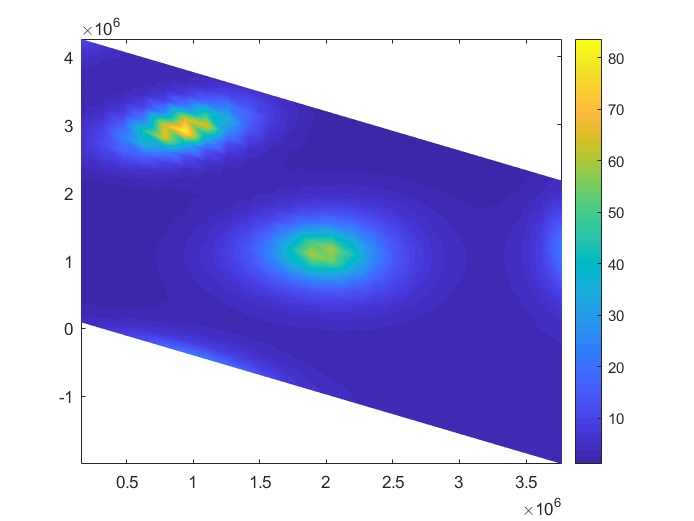


X=zeros(Nkx-1,Nky-1);
Y=zeros(Nkx-1,Nky-1);
for ii=1:(Nkx-1)
    for jj=1:(Nky-1)
        X(ii,jj)=ii*kx_step*sqrt(3)/2;
        Y(ii,jj)=jj*ky_step-ii*kx_step/2;
    end
end
%[X,Y] = meshgrid((kx_start:kx_step:(kx_end-kx_step))/(pi/a),(ky_start:ky_step:(ky_end-ky_step))/(pi/a));
Z = real(berry);
pcolor(X,Y,Z);
shading interp
colorbar